# SNW_VFI_UNEMP (Vectorized) Base Solution Analysis Unemployment

This is the example vignette for function:  [**snw_vfi_main_bisec_vec**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/svalpol/snw_vfi_main_bisec_vec.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for policy function using Exact Vectorized Solution. Base Solution Analysis. Unemployment Shock. The file focuses on the change in value function, asset choice, and consumption choice given a one period unemployment shock (that does not reappear in the future again).

## Test SNW_VFI_UNEMP Defaults Base

Solve the Regular Value and Also the Unemployment Value.

First, solve for value without unemployment issue (use the vectorized code that was previously tested):

mp_params = snw_mp_param('default_base');
mp_controls = snw_mp_control('default_test');
[V_VFI_ss,ap_VFI_ss,cons_VFI_ss,exitflag_VFI_ss] = ...
    snw_vfi_main_bisec_vec(mp_params, mp_controls);

SNW_VFI_MAIN: Finished Age Group:42 of 42
SNW_VFI_MAIN: Finished Age Group:41 of 42
SNW_VFI_MAIN: Finished Age Group:40 of 42
SNW_VFI_MAIN: Finished Age Group:39 of 42
SNW_VFI_MAIN: Finished Age Group:38 of 42
SNW_VFI_MAIN: Finished Age Group:37 of 42
SNW_VFI_MAIN: Finished Age Group:36 of 42
SNW_VFI_MAIN: Finished Age Group:35 of 42
SNW_VFI_MAIN: Finished Age Group:34 of 42
SNW_VFI_MAIN: Finished Age Group:33 of 42
SNW_VFI_MAIN: Finished Age Group:32 of 42
SNW_VFI_MAIN: Finished Age Group:31 of 42
SNW_VFI_MAIN: Finished Age Group:30 of 42
SNW_VFI_MAIN: Finished Age Group:29 of 42
SNW_VFI_MAIN: Finished Age Group:28 of 42
SNW_VFI_MAIN: Finished Age Group:27 of 42
SNW_VFI_MAIN: Finished Age Group:26 of 42
SNW_VFI_MAIN: Finished Age Group:25 of 42
SNW_VFI_MAIN: Finished Age Group:24 of 42
SNW_VFI_MAIN: Finished Age Group:23 of 42
SNW_VFI_MAIN: Finished Age Group:22 of 42
SNW_VFI_MAIN: Finished Age Group:21 of 42
SNW_VFI_MAIN: Finished Age Group:20 of 42
SNW_VFI_MAIN: Finished Age Group:1

Second, solve for the unemployment value, use the exact-bisec result code, call the snw_vfi_main_bisec_vec.m function with a third input of existing value:

mp_params('xi') = 0.5;
mp_params('b') = 0;
[V_VFI_unemp,ap_VFI_unemp,cons_VFI_unemp,exitflag_VFI_unemp] = ...
    snw_vfi_main_bisec_vec(mp_params, mp_controls, V_VFI_ss);

SNW_VFI_MAIN: Finished Age Group:1 of 42
SNW_VFI_MAIN: Finished Age Group:2 of 42
SNW_VFI_MAIN: Finished Age Group:3 of 42
SNW_VFI_MAIN: Finished Age Group:4 of 42
SNW_VFI_MAIN: Finished Age Group:5 of 42
SNW_VFI_MAIN: Finished Age Group:6 of 42
SNW_VFI_MAIN: Finished Age Group:7 of 42
SNW_VFI_MAIN: Finished Age Group:8 of 42
SNW_VFI_MAIN: Finished Age Group:9 of 42
SNW_VFI_MAIN: Finished Age Group:10 of 42
SNW_VFI_MAIN: Finished Age Group:11 of 42
SNW_VFI_MAIN: Finished Age Group:12 of 42
SNW_VFI_MAIN: Finished Age Group:13 of 42
SNW_VFI_MAIN: Finished Age Group:14 of 42
SNW_VFI_MAIN: Finished Age Group:15 of 42
SNW_VFI_MAIN: Finished Age Group:16 of 42
SNW_VFI_MAIN: Finished Age Group:17 of 42
SNW_VFI_MAIN: Finished Age Group:18 of 42
SNW_VFI_MAIN: Finished Age Group:19 of 42
SNW_VFI_MAIN: Finished Age Group:20 of 42
SNW_VFI_MAIN: Finished Age Group:21 of 42
SNW_VFI_MAIN: Finished Age Group:22 of 42
SNW_VFI_MAIN: Finished Age Group:23 of 42
SNW_VFI_MAIN: Finished Age Group:24 of 42
S

## Difference Between Value and Choices In Unemployment and Future Periods

V_VFI_unemp_drop = V_VFI_ss - V_VFI_unemp;
ap_VFI_unemp_drop = ap_VFI_ss - ap_VFI_unemp;
cons_VFI_unemp_drop = cons_VFI_ss - cons_VFI_unemp;

## Base Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 21:2:99, 100];
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('it_legend_select') = 15; % how many shock legends to show
mp_support_graph('cl_colors') = 'jet';

#### MEAN(VAL(A,Z) - VAL(A,Z|unemp)), MEAN(AP(A,Z) - AP(A,Z|unemp)), MEAN(C(A,Z) - C(A,Z|unemp))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(v(A,Z) - v(A,Z|unemp))", V_VFI_unemp_drop, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(v(A,Z) - v(A,Z|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15
    _____    ________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    _

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z) - AP(A,Z|unemp))", ap_VFI_unemp_drop, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z) - AP(A,Z|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15
    _____    ________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z) - C(A,Z|unemp))", cons_VFI_unemp_drop, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z) - C(A,Z|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_eta_1     mean_eta_2     mean_eta_3     mean_eta_4     mean_eta_5     mean_eta_6     mean_eta_7     mean_eta_8     mean_eta_9     mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15
    _____    ________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________

Graph Mean Values Change:

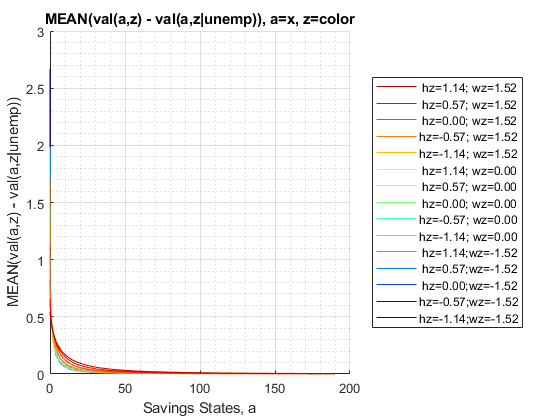

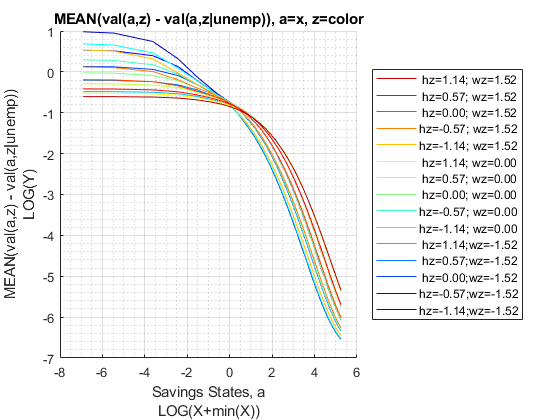

mp_support_graph('cl_st_graph_title') = {'MEAN(val(a,z) - val(a,z|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(val(a,z) - val(a,z|unemp))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Savings Choices Change:

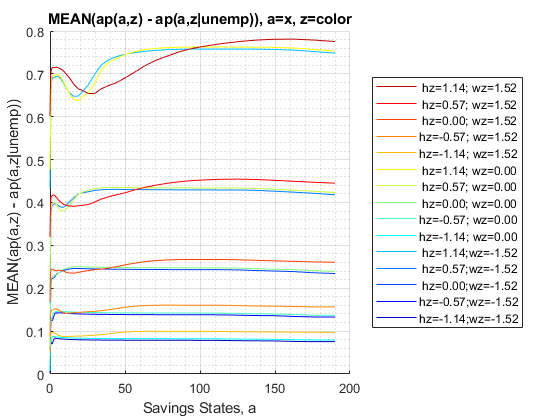

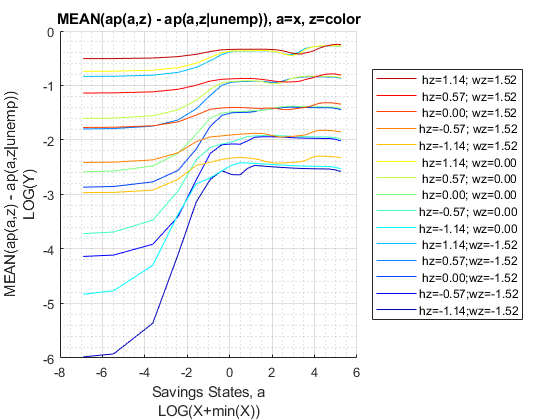

mp_support_graph('cl_st_graph_title') = {'MEAN(ap(a,z) - ap(a,z|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(ap(a,z) - ap(a,z|unemp))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption Change:

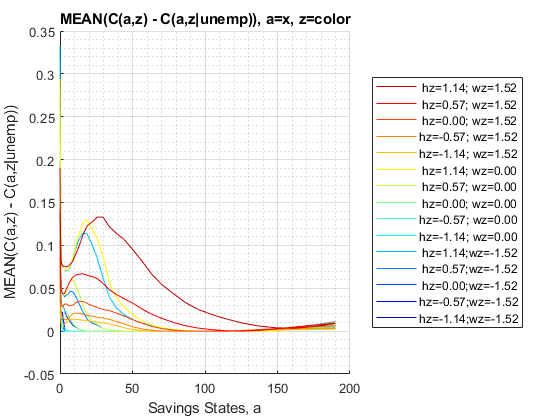

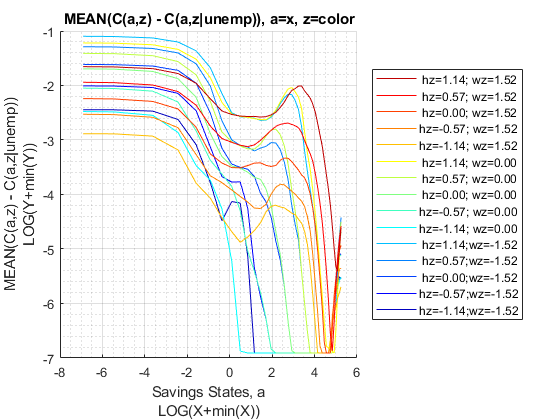

mp_support_graph('cl_st_graph_title') = {'MEAN(C(a,z) - C(a,z|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(a,z) - C(a,z|unemp))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};

#### MEAN(V(KM,J) - V(KM,J | unemp)), MEAN(ap(KM,J) - ap(KM,J | unemp)), MEAN(c(KM,J) - c(KM,J | unemp))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(V(KM,J) - V(KM,J | unemp))", V_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(V(KM,J) - V(KM,J | unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71</

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(ap(KM,J) - ap(KM,J | unemp))", ap_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(ap(KM,J) - ap(KM,J | unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(c(KM,J) - c(KM,J | unemp))", cons_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(c(KM,J) - c(KM,J | unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71</

Graph Mean Values Change:

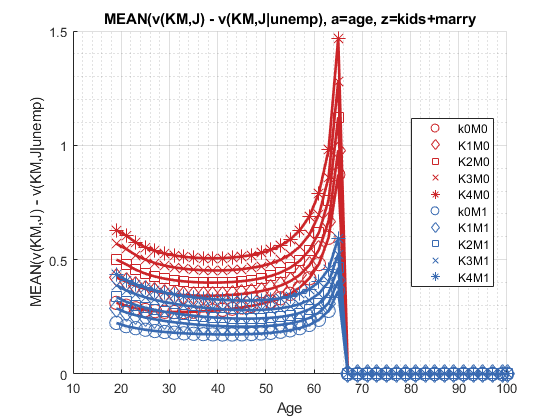

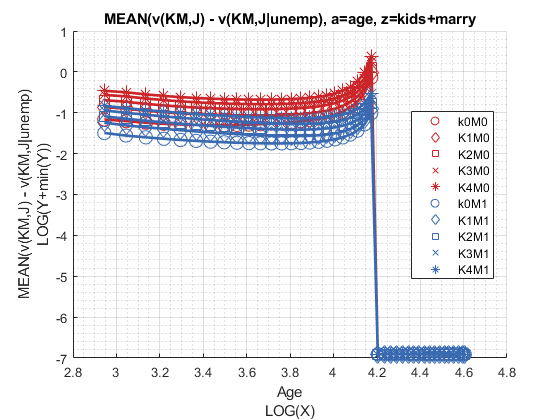

mp_support_graph('cl_st_graph_title') = {'MEAN(v(KM,J) - v(KM,J|unemp), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(v(KM,J) - v(KM,J|unemp)'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices Change:

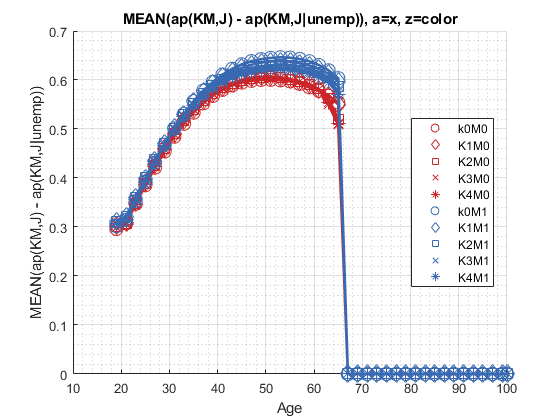

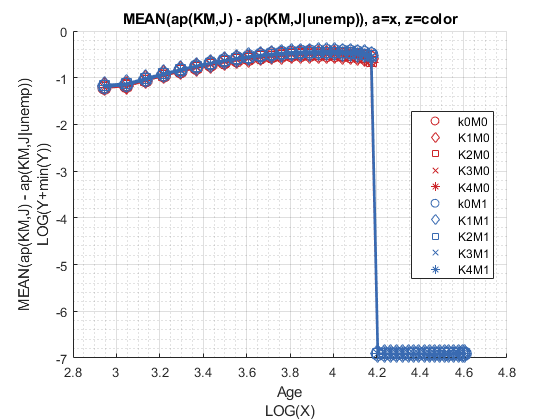

mp_support_graph('cl_st_graph_title') = {'MEAN(ap(KM,J) - ap(KM,J|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(ap(KM,J) - ap(KM,J|unemp))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption Change:

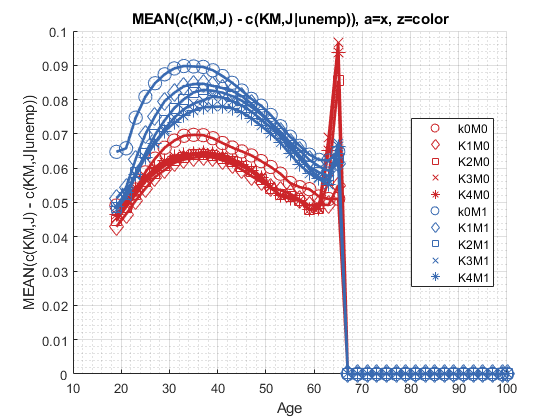

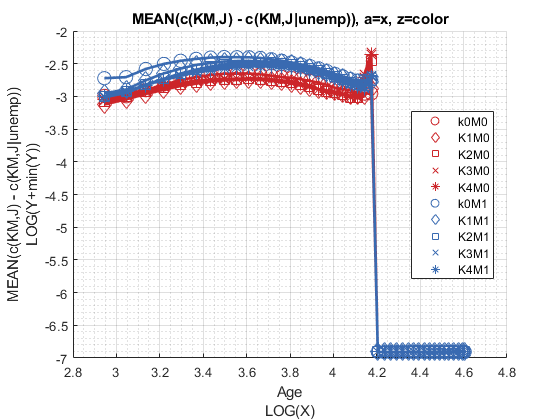

mp_support_graph('cl_st_graph_title') = {'MEAN(c(KM,J) - c(KM,J|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(c(KM,J) - c(KM,J|unemp))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(v(EKM,J) - v(EKM,J|unemp)), MEAN(ap(EM,J) - ap(EM,J|unemp)), MEAN(c(EM,J) - c(EM,J|unemp))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(v(EM,J) - v(EM,J|unemp))", V_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(v(EM,J) - v(EM,J|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(ap(EM,J) - ap(EM,J|unemp))", ap_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(ap(EM,J) - ap(EM,J|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(c(EM,J) - c(EM,J|unemp))", cons_VFI_unemp_drop, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(c(EM,J) - c(EM,J|unemp))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_21    mean_age_23    mean_age_25    mean_age_27    mean_age_29    mean_age_31    mean_age_33    mean_age_35    mean_age_37    mean_age_39    mean_age_41    mean_age_43    mean_age_45    mean_age_47    mean_age_49    mean_age_51    mean_age_53    mean_age_55    mean_age_57    mean_age_59    mean_age_61    mean_age_63    mean_age_65    mean_age_67    mean_age_69    mean_age_71

Graph Mean Values Change:

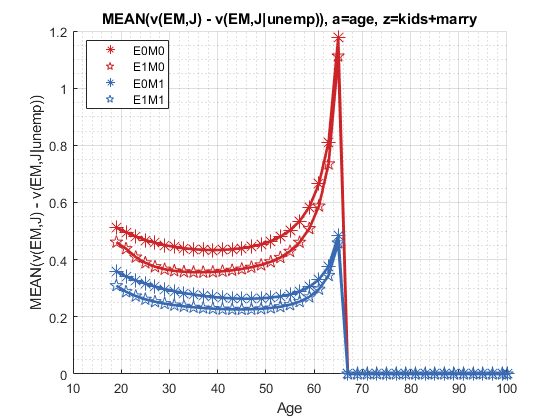

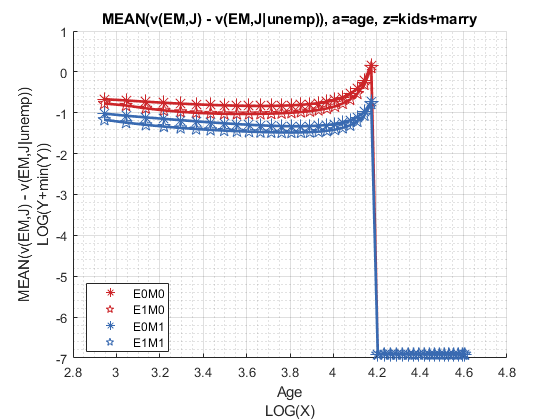

mp_support_graph('cl_st_graph_title') = {'MEAN(v(EM,J) - v(EM,J|unemp)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(v(EM,J) - v(EM,J|unemp))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices Change:

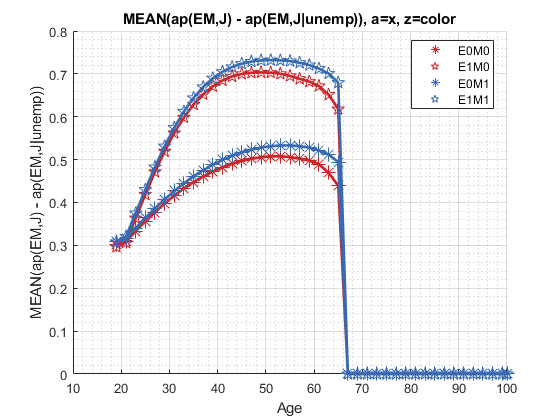

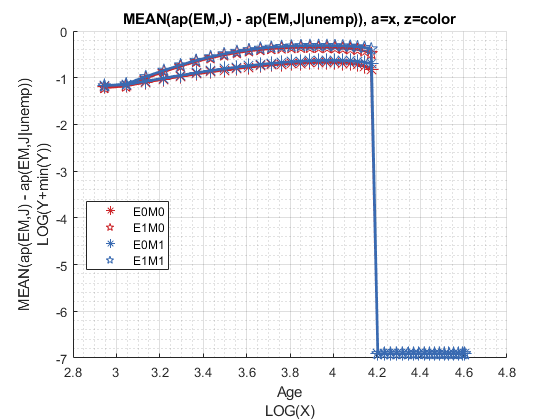

mp_support_graph('cl_st_graph_title') = {'MEAN(ap(EM,J) - ap(EM,J|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(ap(EM,J) - ap(EM,J|unemp))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption Change:

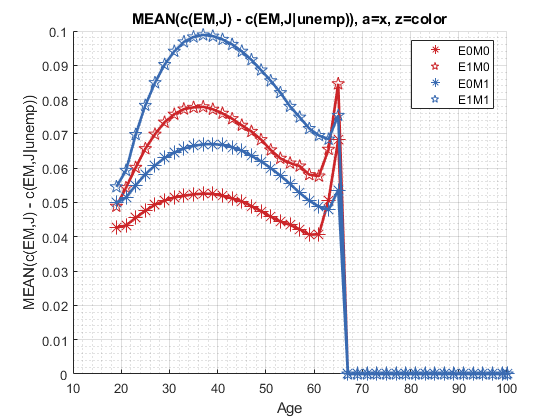

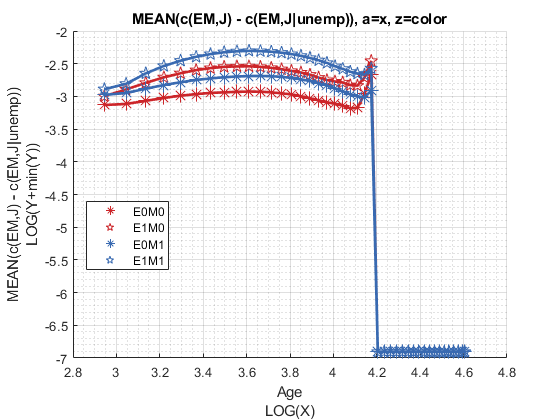

mp_support_graph('cl_st_graph_title') = {'MEAN(c(EM,J) - c(EM,J|unemp)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(c(EM,J) - c(EM,J|unemp))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);